**Create a Demonstration Lane System**

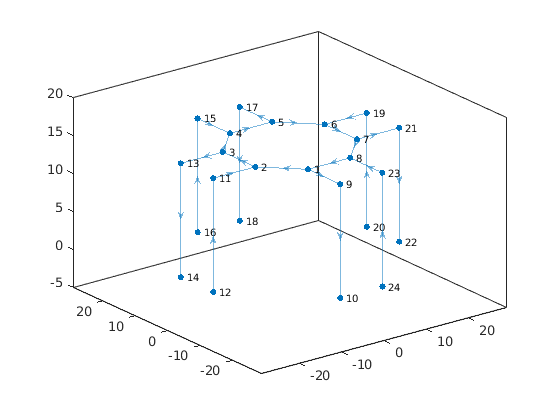

lbsd = LBSD.genSampleLanes(10, 15);
clf
plot(lbsd);

**List the lane ids**

lane_ids = lbsd.getLaneIds

lane_ids = 24×1 string array
    "2"
    "9"
    "3"
    "4"
    "13"
    "5"
    "6"
    "17"
    "7"
    "8"
    "21"
    "1"
    "10"
    "12"
    "11"
    "14"
    "16"
    "15"
    "18"
    "20"
    "19"
    "22"
    "24"
    "23"


**Checkout the lane node table**

lbsd.lane_graph.Nodes

ans = 24×6 table
           XData      YData     ZData    Launch    Land     Name 
          _______    _______    _____    ______    ____    ______

    1          -5    -12.071     15        0        0      {'1' }
    2     -12.071         -5     15        0        0      {'2' }
    3     -12.071          5     15        0        0      {'3' }
    4          -5     12.071     15        0        0      {'4' }
    5           5     12.071     15        0        0      {'5' }
    6      12.071          5     15        0        0      {'6' }
    7      12.071         -5     15        0        0      {'7' }
    8           5    -12.071     15        0    

**Checkout the lane edge table**

lbsd.lane_graph.Edges

ans = 24×2 table
              EndNodes        Weight
          ________________    ______

    2     {'1' }    {'2' }      10  
    9     {'1' }    {'9' }      10  
    3     {'2' }    {'3' }      10  
    4     {'3' }    {'4' }      10  
    13    {'3' }    {'13'}      10  
    5     {'4' }    {'5' }      10  
    6     {'5' }    {'6' }      10  
    17    {'5' }    {'17'}      10  
    7     {'6' }    {'7' }      10  
    8     {'7' }    {'8' }      10  
    21    {'7' }    {'21'}      10  
    1     {'8' }    {'1' }      10  
    10    {'9' }    {'10'}      15  
    12    {'11'}    {'2' }      10  
    11    {'12'}    {'11'}      15  
    14    {'1

**Generate Some Random Reservations:**

start_time = 0;
end_time = 100;
lane_ids = ["1","2","3"];
num_res = 50;
speed = 1;
headway = 5;
lbsd.genRandReservations(start_time, end_time, num_res, lane_ids, speed, headway);

**Get the Reservation Table**

lbsd.getReservations

ans = 42×6 table
     id     lane_id    entry_time_s    exit_time_s    speed    hd
    ____    _______    ____________    ___________    _____    __

    "1"       "1"         16.218         26.218         1      5 
    "2"       "1"         79.428         89.428         1      5 
    "3"       "1"         31.122         41.122         1      5 
    "4"       "1"         52.853         62.853         1      5 
    "5"       "1"         60.198         70.198         1      5 
    "6"       "1"         65.408         75.408         1      5 
    "7"       "1"         45.054         55.054         1      5 
    "8"       "1"         8.3821         18.382         1      5 
    "9"       "1"         22.898         32.898         1      5 
    "10"      "1"         91.334         101.33     

lane_id = lbsd.getLaneIdFromResId("2")

lane_id = "1"

**Get the Reservation Table for Specific Lane**

lbsd.getLaneReservations("1")

ans = 14×6 table
     id     lane_id    entry_time_s    exit_time_s    speed    hd
    ____    _______    ____________    ___________    _____    __

    "1"       "1"         16.218         26.218         1      5 
    "2"       "1"         79.428         89.428         1      5 
    "3"       "1"         31.122         41.122         1      5 
    "4"       "1"         52.853         62.853         1      5 
    "5"       "1"         60.198         70.198         1      5 
    "6"       "1"         65.408         75.408         1      5 
    "7"       "1"         45.054         55.054         1      5 
    "8"       "1"         8.3821         18.382         1      5 
    "9"       "1"         22.898         32.898         1      5 
    "10"      "1"         91.334         101.33     

**Clear Reservations**

lbsd.clearReservations()

**This object also publishes events each time a reservation is made for testing with the ATOC. Here''s a simple example:**

**Subscribe to events**

lbsd.subscribeToNewReservation(@(src,evt)disp("Reservation Made!"));

**Then if you run the same experiment as above you'll see something like this:**

start_time = 0;
end_time = 100;
lane_ids = ["1","2","3"];
num_res = 50;
speed = 1;
headway = 5;
lbsd.genRandReservations(start_time, end_time, num_res, lane_ids, speed, headway);

Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!


**View Lane Reservations in ATOC**

% atoc = ATOC(lbsd, 100, zeros(3), 90);
% atoc.laneGraphs(lane_ids, [start_time, end_time]);